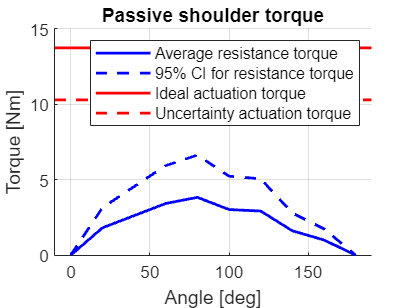

Length = 0.266+0.2475;
Weight = 40*9.81;

Length_with_SD = 0.266+2*0.0094+0.2475+2*0.0095;
Weight_with_SD = 64.5*9.81;

shoulder_torque = [0 0.009 0.013 0.017 0.019 0.015 0.0145 0.008 0.005 0]*Length*Weight;
shoulder_torque_with_SD = [0 0.009 0.013 0.017 0.019 0.015 0.0145 0.008 0.005 0]*Length_with_SD*Weight_with_SD;

angle = linspace(0,180,10);
angle_extended = linspace(-10,190,10);
Ideal_motor_torque = 0.686*20*ones(1,10);
%motor_torque = 

clf
hold on;
plot(angle,shoulder_torque,'LineWidth',1.5,'Color','b')
plot(angle,shoulder_torque_with_SD,'--','LineWidth',1.5,'Color','b')
plot(angle_extended,Ideal_motor_torque,'LineWidth',1.5,'Color','r')
plot(angle_extended,Ideal_motor_torque*0.75,'--','LineWidth',1.5,'Color','r')


grid on; 
xlim([-10 190])
ylim([0 15])
title('Passive shoulder torque')
xlabel('Angle [deg]')
ylabel('Torque [Nm]')
legend('Average resistance torque','95% CI for resistance torque','Ideal actuation torque','Uncertainty actuation torque')